% DNL and INL
Iin = 0.7166565; %uA
LSB = Iin / 128;
x = linspace(1,128,128);
y = LSB * x;
plot(x, y,'ro')
hold on


% plot ideal

file_path = "dac_simulation_ideal_24_4_resistor_100.txt"

file_path = "dac_simulation_ideal_24_4_resistor_100.txt"

file = fopen(file_path, 'r');

ideal_current_list = [];
while ~feof(file)
    i = i + 1;
    line = fgetl(file);
    line = strtrim(line);
    if numel(line) >= 15 && i>1
            result_char = line(end-15:end);
            disp(result_char);
            result_current = str2double(result_char);
            ideal_current_list(end + 1) = result_current; 
    end
end 

        i(viout)
  2.48557797e-09
  1.25768210e-07
  1.28950646e-07
  1.61477999e-07
  1.35311851e-07
  1.78213213e-07
  1.69681741e-07
  1.83330513e-07
  1.48039291e-07
  1.93206318e-07
  1.91012091e-07
  2.06506868e-07
  1.86103122e-07
  2.11175305e-07
  2.01256782e-07
  2.08096864e-07
  1.73542404e-07
  2.15029459e-07
  2.15559510e-07
  2.30037685e-07
  2.16674025e-07
  2.37389600e-07
  2.32258003e-07
  2.39029461e-07
  2.19106369e-07
  2.43534856e-07
  2.41674698e-07
  2.50537269e-07
  2.37347052e-07
  2.52572590e-07
  2.45597931e-07
  2.49533514e-07
  2.25136105e-07
  2.55158099e-07
  2.57001773e-07
  2.67711997e-07
  2.60793485e-07
  2.74805004e-07
  2.73082293e-07
  2.78323782e-07
  2.68802609e-07
  2.83432740e-07
  2.83812369e-07
  2.89662665e-07
  2.84662789e-07
  2.93282810e-07
  2.91565129e-07
  2.94797644e-07
  2.86843743e-07
  2.99375372e-07
  3.00922551e-07
  3.06082200e-07
  3.04251643e-07
  3.10715834e-07
  3.11083113e-07
  3.14142838e-07
  3.12033194e-07
  3.18379932e-

fclose(file);
ideal_current_list = ideal_current_list(2:end)

ideal_current_list = 	1.0e+-6 *

    0.0025    0.1258    0.1290    0.1615    0.1353    0.1782    0.1697    0.1833    0.1480    0.1932    0.1910    0.2065    0.1861    0.2112    0.2013    0.2081    0.1735    0.2150    0.2156    0.2300    0.2167    0.2374    0.2323    0.2390    0.2191    0.2435    0.2417    0.2505    0.2373    0.2526    0.2456    0.2495    0.2251    0.2552    0.2570    0.2677    0.2608    0.2748    0.2731    0.2783    0.2688    0.2834    0.2838    0.2897    0.2847    0.2933    0.2916    0.2948    0.2868    0.2994


plot([1:128],1000000*ideal_current_list,"b-","LineWidth",2)
hold on

% plot 30 MC runs
difference = [];

for run= 1:10
file_path = sprintf('dac_simulation_mc_24_4_resistor_100_%d.txt', run);
i = 0;
current_list = [];
file = fopen(file_path, 'r');

while ~feof(file)
    i = i + 1;
    line = fgetl(file);
    line = strtrim(line);
    if numel(line) >= 15 && i>1
            result_char = line(end-15:end);
            disp(result_char);
            result_current = str2double(result_char);
            current_list(end + 1) = result_current; 
    end
end

fclose(file);
plot([1:128],1000000*current_list,".-")
ylabel("current(uA)")
xlabel("bit value")
hold on

difference(run, :) = current_list - ideal_current_list;
end

  3.53868757e-09
  6.96645884e-07
  6.98470544e-07
  7.52239401e-07
  7.01535157e-07
  7.58324660e-07
  7.53201121e-07
  7.58646379e-07
  7.07565505e-07
  7.60269543e-07
  7.59085054e-07
  7.62049069e-07
  7.54869518e-07
  7.62170757e-07
  7.59606621e-07
  7.60867437e-07
  7.17357395e-07
  7.61460896e-07
  7.61127808e-07
  7.63106669e-07
  7.60273124e-07
  7.63465977e-07
  7.62658559e-07
  7.63257361e-07
  7.57359047e-07
  7.63329524e-07
  7.62847364e-07
  7.63650959e-07
  7.61021596e-07
  7.63463774e-07
  7.61992908e-07
  7.62362319e-07
  7.30600092e-07
  7.62596542e-07
  7.62517587e-07
  7.63814114e-07
  7.62333755e-07
  7.64121140e-07
  7.63730597e-07
  7.64087417e-07
  7.61883328e-07
  7.64201744e-07
  7.64029963e-07
  7.64416242e-07
  7.63517875e-07
  7.64395352e-07
  7.63937123e-07
  7.64096640e-07
  7.60319153e-07
  7.64138491e-07
  7.64030602e-07
  7.64490011e-07
  7.63751430e-07
  7.64565158e-07
  7.64274731e-07
  7.64447861e-07
  7.62729186e-07
  7.64424342e-07
  7.64201602e-

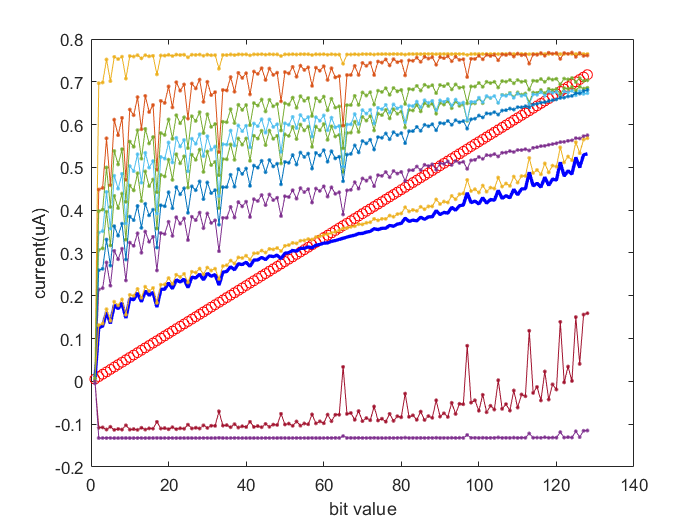

hold off 

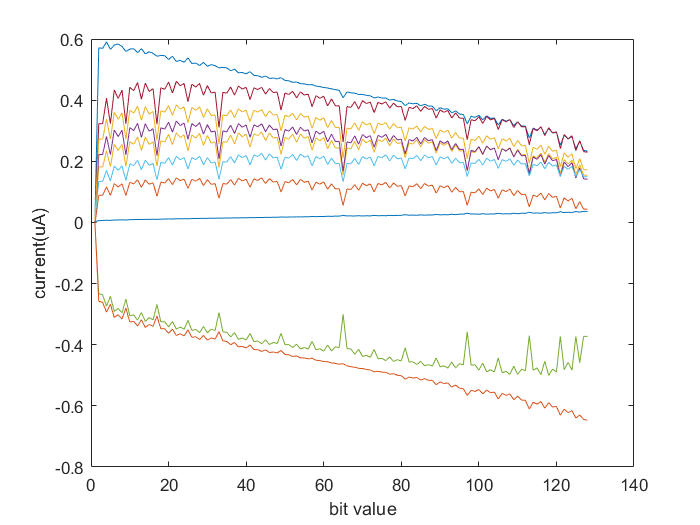

figure
plot([1:128],1000000*difference)
ylabel("current(uA)")
    xlabel("bit value")